clear
%read all images, normalize and create eigenfaces
commonsize = [300,300];
[DataMatrix, ImageFiles] = normalize_all_images("../db/DB1/", commonsize);
[meanface, eigenVectors, weights] = compute_eigenfaces(DataMatrix,commonsize);

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9961    1.0000    1.0000    1.0000    1.0000    0.9961    1.0000    1.0000    1.0000    1.0000


ans =    18.0786   29.7151   27.7817   11.3716   12.5511   11.2478   18.5452   14.0623   11.9948   29.0270   10.1127   28.4371   15.6371   14.4000   22.2999   34.3701


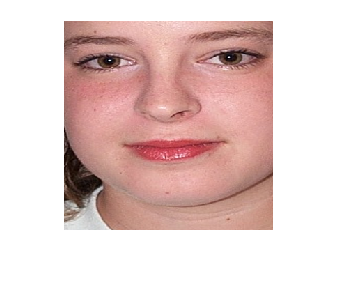

img = imread("..\db\DB1\db1_13.jpg");
% img = imrotate(img,5,"bicubic"); %5 -> 11/16 correct, -5 9/16 correct
% scale = size(im2gray(img))*0.9;
% img = imresize(img,round(scale));
% img = img*0.9;


id = isPersonInSet(img, meanface, eigenVectors, commonsize);

id

id = 13

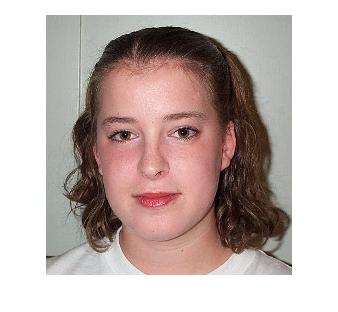

if id < 1
    error = 404
elseif id < 10
    identified_img = imread("..\db\DB1\db1_0" + id +".jpg");
    imshow(identified_img)
else
    identified_img = imread("..\db\DB1\db1_" + id +".jpg");
    imshow(identified_img)
end

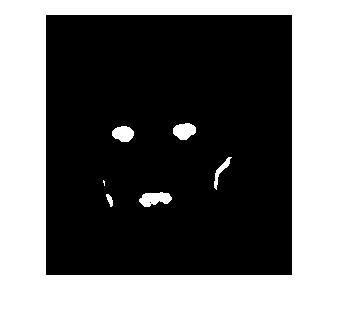

img_gw = gray_world(img);
[face_mask, eye_mask, mouth_mask] = create_masks(img_gw);